# Parametric Duffing Oscillator

Coupled parametric duffing oscillators along the lines of 

Szabelski, K. & Warminski, J. Self-excited System Vibrations with Parametric and External Excitations.Journalof Sound and Vibration187,595–607 (4 1995). [https://doi.org/10.1006/jsvi.1995.0547](https://doi.org/10.1006/jsvi.1995.0547) 

The model considered here is given as 

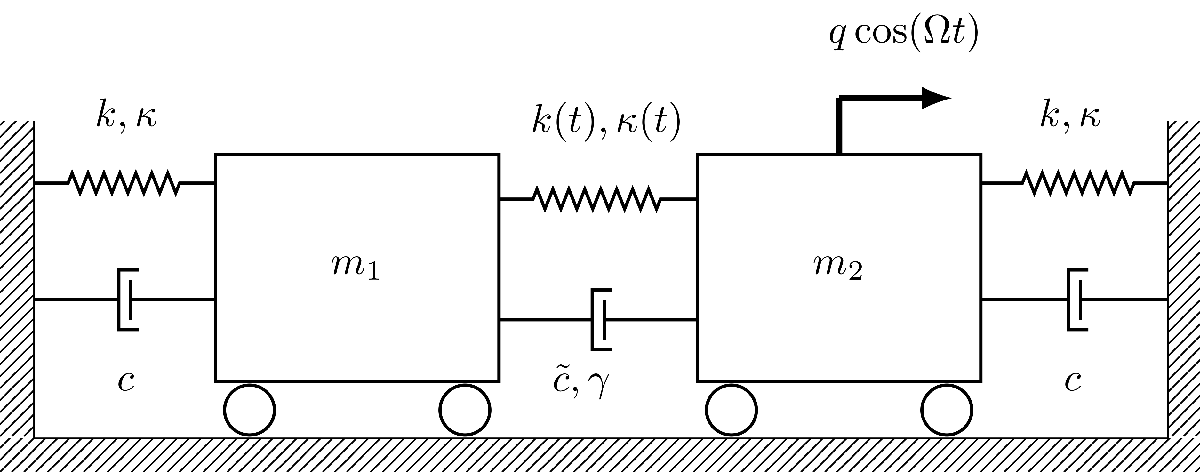

The linear and nonlinear stiffness of the coupling spring is varying in a periodic fashion. Furthermore the damping coefficient $\tilde{c}$ is negative, which leads to self excitation. The resulting exponentially growing amplitudes are stabilised by nonlinear damping.

clear all;clc

## system parameters

mu1 = 0.3;
mu3 = 0.3;

## Generate model

[ M,C,K,fnl,fext] = build_model(mu1,mu3);

## Dynamical system setup

We consider the forced  and parametrically excited system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})=\epsilon\mathbf{g}(\mathbf{x},\dot{\mathbf{x}},\Omega t),$$


which can be written in the first-order form as 


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{G}(\mathbf{z},\phi),\\\dot{\mathbf{\phi}}	
=\mathbf{\Omega}$$


where

$\mathbf{z}=\left[\begin{array}{c}\mathbf{x}\\\dot{\mathbf{x}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}-\mathbf{K} 
& \mathbf{0}\\\mathbf{0} & \mathbf{M}\end{array}\right],\mathbf{B}=\left[\begin{array}{cc}\mathbf{C} 
& \mathbf{M}\\\mathbf{M} & \mathbf{0}\end{array}\right],\quad\quad\mathbf{F}(\mathbf{z})=\left[\begin{array}{c}\mathbf{-\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})}\\\mathbf{0}\end{array}\right],\quad\mathbf{G}(\mathbf{z},\mathbf{\phi})=\left[\begin{array}{c}
\mathbf{g}(\mathbf{x, \dot{x}},\phi)\\
\mathbf{0}
\end{array}\right]$.

DS = DynamicalSystem();
set(DS,'M',M, 'C', C, 'K',K,'fnl',fnl);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')

## Add forcing

The dynamical system is forced externally and parametrically with $\mathbf{g(x},\Omega t) = 
\mu\left[\begin{array}{cc} k & -k \\ -k &  k \end{array}\right] \cos(2\Omega t) \mathbf{x} 
+
 \kappa\mu \cos (2 \Omega t) \left[\begin{array}{cc}  -(x_1-x_2)^3 \\   (x_1-x_2)^3   \end{array}\right] 
    + \left[\begin{array}{cc}   0 \\ q \cos (\Omega t)   \end{array}\right]$

DS.add_forcing(fext,1);

## Linear Modal Analysis 

% Analyse spectrum
[V,D,W] = DS.linear_spectral_analysis();


 The first 4 eigenvalues are given as 
   0.0500 + 1.7313i
   0.0500 - 1.7313i
  -0.0500 + 0.9987i
  -0.0500 - 0.9987i



**Choose Master subspace (perform resonance analysis)**

S = SSM(DS);
set(S.Options, 'reltol', 0.5,'notation','multiindex')

%Choose Master subspace
masterModes = [1,2];
S.choose_E(masterModes);

sigma_out = -1
sigma_in = -1


## Forced response curves using SSMs

Obtaining **forced response curve** in reduced-polar coordinate

order = 5; % Approximation order

setup options

outdof = 1;
set(S.Options, 'reltol', 0.5,'IRtol',0.02,'notation', 'multiindex','contribNonAuto',true)
set(S.FRCOptions, 'nt', 2^7, 'nRho', 200, 'nPar', 100, 'nPsi', 200, 'rhoScale', 6 )
set(S.FRCOptions, 'method','level set') 
set(S.FRCOptions, 'outdof',outdof)

choose frequency range around the master mode frequency

omega0     = imag(S.E.spectrum(1));
OmegaRange = omega0*[0.8 1.3]; 
epsSamp = [0.2 ,0.5,0.8];

Extract forced response curves for different forcing amplitudes

*****************************************
Calculating FRC using SSM with master subspace: [1  2]
sigma_out = -1
sigma_in = -1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 8.23E-03 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 9.56E-03 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 1.17E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 1.45E-02 MB
gamma = 
  -0.0063 + 0.0139i
  -0.0000 - 0.0002i



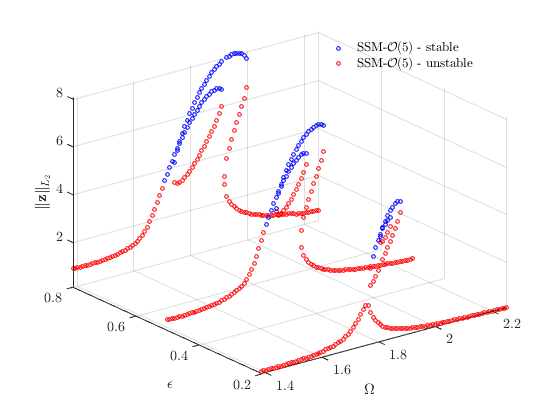

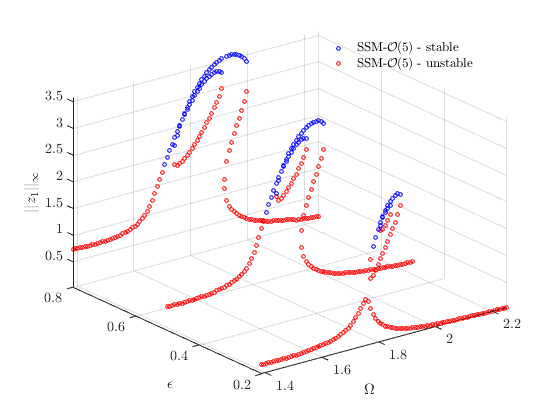

Total time spent on FRC computation upto O(5) = 00:01:44


startFRCSSM = tic;
Sweep = S.SSM_lvlSweeps( OmegaRange, epsSamp, order);

timings.FRCSSM = toc(startFRCSSM)

timings = struct with fields:
    FRCSSM: 104.1953


figFRC = gcf;

## Verification: Collocation using [coco](https://sourceforge.net/p/cocotools/wiki/Home/)

Dankowicz, H., & Schilder, F. (2013).  *Recipes for Continuation,* SIAM Philadelphia. [<https://doi.org/10.1137/1.9781611972573](https://doi.org/10.1137/1.9781611972573)>

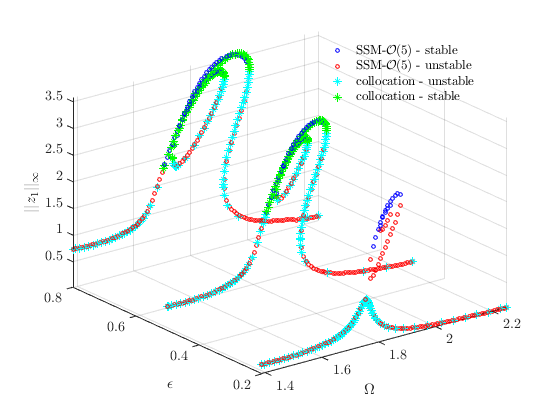


 Run='FRC0.2': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          2.42e+00  2.43e+01    0.3    0.0    0.0
   1   1  1.20e-01  2.16e+01  2.12e+00  2.18e+01    0.3    0.4    0.0
   2   1  1.20e-01  1.94e+01  1.87e+00  1.95e+01    0.3    1.0    0.1
   3   1  1.21e-01  1.73e+01  1.64e+00  1.75e+01    0.3    1.2    0.1
   4   1  1.22e-01  1.54e+01  1.44e+00  1.58e+01    0.4    1.4    0.1
   5   1  1.23e-01  1.36e+01  1.27e+00  1.42e+01    0.4    1.5    0.1
   6   1  1.24e-01  1.21e+01  1.11e+00  1.29e+01    0.4    1.6    0.1
   7   1  1.27e-01  1.06e+01  9.69e-01  1.17e+01    0.4    1.7    0.1
   8   1  1.29e-01  9.34e+00  8.43e-01  1.06e+01    0.4    1.7    0.1
   9   1  1.33e-01  8.17e+00  7.31e-01  9.74e+00    0.4    2.1    0.1
  10   1  1.37e-01  7.11e+00  6.31e-01  8.97e+00    0.4    2.1    0.1
  11   1  1.43e-01  6.15e+00 

nCycles = 10;

coco = cocoWrapper(DS, nCycles, outdof);
set(coco,'initialGuess','forward')
set(coco.Options, 'NAdapt', 1);
set(coco.Options,'ItMX',30,'NTST', 30,'PtMX',500); 

figure(figFRC)
hold on

startcoco = tic;
Sweep_po = coco.coco_poSweeps(epsSamp,OmegaRange);

timings.cocoFRC = toc(startcoco)

timings = struct with fields:
     FRCSSM: 104.1953
    cocoFRC: 274.2873


figFRCcc = gcf;

## Verification of the Isola

% Initial Condition on Isola
load('FRC_IC.mat')
DS.add_forcing(fext,0.2);
IC = FRC.Zic.'

IC =    -0.2073
    0.1158
    3.6121
   -3.5975


OmegaIC = FRC.Omega

OmegaIC = 1.7890

nCycles = 10;

coco_ic = cocoWrapper(DS, nCycles, outdof);
set(coco_ic,'initialGuess','linear')
set(coco_ic.Options, 'NAdapt', 1);
set(coco_ic.Options,'ItMX',100,'NTST', 40,'PtMX',100,'bi_direct',false); 
PlotFRC = false;

figure(figFRC)
startcoco = tic;
Isola = coco.extract_FRC_fromIC(OmegaRange,IC,OmegaIC,PlotFRC)


 Run='FRC0.2': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          6.90e-03  5.82e+01    0.0    0.0    0.0
   1   1  1.00e+00  6.71e-01  8.55e-05  5.79e+01    0.0    0.1    0.0
   2   1  1.00e+00  1.46e-02  4.43e-08  5.79e+01    0.0    0.1    0.0
   3   1  1.00e+00  8.98e-06  2.52e-14  5.79e+01    0.0    0.2    0.0
   4   1  1.00e+00  2.29e-12  2.03e-14  5.79e+01    0.0    0.2    0.0

 STEP      TIME        ||U||  LABEL  TYPE         omega    po.period          eps         amp1
    0  00:00:00   5.7937e+01      1  EP      1.7890e+00   3.5120e+00   2.0000e-01   2.0244e+00
    1  00:00:01   5.7797e+01      2  EP      1.7890e+00   3.5120e+00   2.0000e-01   2.0242e+00

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                  

Isola = 1×1 cell array
    {111×28 cell}


timings.cocoIsola = toc(startcoco)

timings = struct with fields:
       FRCSSM: 104.1953
      cocoFRC: 274.2873
    cocoIsola: 70.9313


## Plot for Paper

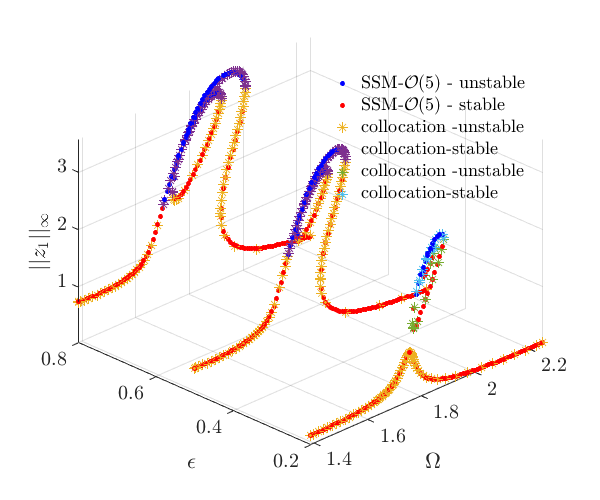

PaperSweepPlot(Sweep,Sweep_po,1,5,Isola)